clc
clear

addpath(genpath('..\Toolboxes\SoRoRim\Basic functions'))
addpath('..\Toolboxes\SoRoRim\Custom')

addpath('..\Toolboxes\SoRoRim\SorosimLink files')

addpath('..\Toolboxes\SoRoRim\SorosimTwist files')

addpath(genpath('..\Toolboxes\SoRoRim\SorosimLinkage files')) %include subfolders

load('C:\Users\Fadli\Desktop\workspace\FinalProject_SoftRobotic_DeepReinforcementLearning\src\matlab\src\generate\mat\link1.mat')
load('C:\Users\Fadli\Desktop\workspace\FinalProject_SoftRobotic_DeepReinforcementLearning\src\matlab\src\generate\mat\linkage1.mat')

Time-advancing

                                             Norm of      First-order   Trust-region
 Iteration  Func-count     ||f(x)||^2           step       optimality         radius
     0         13         2.84722e+14                         3.2e+14              1
     1         26         1.12642e+11       0.695007         6.21e+12              1
     2         39             7819.75      0.0687158         1.66e+09           1.74
     3         52         1.98625e-10    3.32204e-05              301           1.74
     4         65         2.33321e-17    5.73285e-10           0.0937           1.74
     5         78          6.9595e-18    2.43761e-13           0.0534           1.74

Equation solved, solver stalled.

fsolve stopped because the relative size of the current step is less than the
value of the 

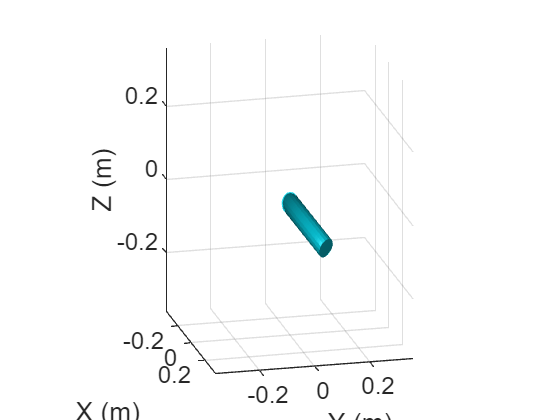

q =     0.0000
    0.0000
   -0.0000
    0.0000
    0.3931
   -0.0041
    0.2446
   -0.1622
    0.3931
   -0.0041


% static simulation

clc

q = linkage1.statics


cp = linkage1.PlotParameters.CameraPosition

cp =     0.6000   -0.1500    0.1500



%q=linkage1.statics([1, 2, 3, 4], zeros(18, 1))

% dynamic simulation

clc

[t,qqd] = linkage1.dynamics;

clc
clear

host = '127.0.0.1'; 
port = 3000;      

try
    tcpClient = tcpclient(host, port);
    disp('Connected to the server.');

    while true
        dataToSend = struct('data', [1, 2, 3])
        if strcmpi(dataToSend, 'exit')
            break;
        end

        write(tcpClient, uint8(jsonencode(dataToSend)));
        
        disp("pause 10 seconds");
        pause(10);
        disp("pause passed")
        
        if tcpClient.BytesAvailable > 0
            response = read(tcpClient, tcpClient.BytesAvailable);
            responseJson = jsondecode(char(response));

            data = responseJson.data
            disp("Response from server:");
            disp(data);
        end
        
    end
catch ME

    disp("An error occurred:");
    disp(ME.message);
end


clear tcpClient;
disp('Disconnected from the server.');
